## **FEATURE MANIPULATION EXP7 **

**This experiment is to try to analyze the overfitting of the created models from FM_Exp1-6.**

**For doing so, we will solve different instance sets, according to the type of instances used by creating the models. **

**For example, HH0 was created for solving properly two instances: one LPTvsALL and one SPTvsALL. **

**What will happen if we solve a whole set of instances containing LPTSvsALL + SPTvsALL. **

**Will it outperform the single heuristics? **

**And so on... **

**CLEANING AND FOLDERS**

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

**LOADING FILES**

%Loading heuristics
load('LPT.mat')
load('SPT.mat')
load('MPA.mat')
load('MPA_multi.mat')
load('LPA.mat')


%Loading HH0-3
load('FM_HH0.mat')
load('FM_HH1.mat')
load('FM_HH1_multi.mat')
load('FM_HH2.mat')
load('FM_HH2_multi.mat')
load('FM_HH3.mat')
load('FM_HH3_multi.mat')

%Loading SHH1-5 
load("FM_SHH1.mat")
load("FM_SHH2.mat")
load("FM_SHH3.mat")
load("FM_SHH4.mat")
load("FM_SHH5.mat")

%Loading CHH1 
load("FM_CHH1.mat")

%Loading Instances
load("instances_adv1_adv2_comb.mat")

**BREAKING DOWN DE INSTANCES INTO 4 SUBSETS **

LPAinstances=[instances_comb(1:30) instances_comb(121:150)];
MPAinstances=[instances_comb(31:60) instances_comb(151:180)];
SPTinstances=[instances_comb(61:90) instances_comb(181:210)];
LPTinstances=[instances_comb(91:120) instances_comb(211:240)];

**SAVING FILES **

save('LPAinstances','LPAinstances')
save('MPAinstances','MPAinstances')
save('LPTinstances','LPTinstances')
save('SPTinstances','SPTinstances')

**LET'S START WITH HH0: it was tailored to solve a SPT and LPT instance.  **

%Solving LPT instances with LPT,SPT and HH0
solvedLPTInstances_HH0=FM_HH0.solveInstanceSet(LPTinstances);
solvedLPTInstances_LPT=LPT.solveInstanceSet(LPTinstances);
solvedLPTInstances_SPT=SPT.solveInstanceSet(LPTinstances);

%Retrieving makespans 
for x=1:length(LPTinstances)
    LPTInstances_makespans_HH0(x)=solvedLPTInstances_HH0{x}.solution.makespan;
    LPTInstances_makespans_LPT(x)=solvedLPTInstances_LPT{x}.solution.makespan;
    LPTInstances_makespans_SPT(x)=solvedLPTInstances_SPT{x}.solution.makespan;
end

%Solving SPT instances with LPT,SPT and HH0
solvedSPTInstances_HH0=FM_HH0.solveInstanceSet(SPTinstances);
solvedSPTInstances_LPT=LPT.solveInstanceSet(SPTinstances);
solvedSPTInstances_SPT=SPT.solveInstanceSet(SPTinstances);

for x=1:length(SPTinstances)
    SPTInstances_makespans_HH0(x)=solvedSPTInstances_HH0{x}.solution.makespan;
    SPTInstances_makespans_LPT(x)=solvedSPTInstances_LPT{x}.solution.makespan;
    SPTInstances_makespans_SPT(x)=solvedSPTInstances_SPT{x}.solution.makespan;
end

%Solving both SPT and LPT instances with LPT,SPT and HH0
LPT_SPTinstances=[LPTinstances SPTinstances];
solvedLPT_SPTInstances_HH0=FM_HH0.solveInstanceSet(LPT_SPTinstances);
solvedLPT_SPTInstances_LPT=LPT.solveInstanceSet(LPT_SPTinstances);
solvedLPT_SPTInstances_SPT=SPT.solveInstanceSet(LPT_SPTinstances);

for x=1:length(LPT_SPTinstances)
    LPT_SPTInstances_makespans_HH0(x)=solvedLPT_SPTInstances_HH0{x}.solution.makespan;
    LPT_SPTInstances_makespans_LPT(x)=solvedLPT_SPTInstances_LPT{x}.solution.makespan;
    LPT_SPTInstances_makespans_SPT(x)=solvedLPT_SPTInstances_SPT{x}.solution.makespan;
end

**LET'S LOOK AT THE RESULTS BY OBTAINING THE MEAN OF ALL RUNS **

%frame
Results_FM_Exp7_0{2,1}="LPT";
Results_FM_Exp7_0{3,1}="SPT";
Results_FM_Exp7_0{4,1}="HH0";
Results_FM_Exp7_0{1,2}="LPT instances";
Results_FM_Exp7_0{1,3}="SPT instances";
Results_FM_Exp7_0{1,4}="LPT + SPT instances";

%results
Results_FM_Exp7_0{2,2}=mean(LPTInstances_makespans_LPT);
Results_FM_Exp7_0{3,2}=mean(LPTInstances_makespans_SPT);
Results_FM_Exp7_0{4,2}=mean(LPTInstances_makespans_HH0);

Results_FM_Exp7_0{2,3}=mean(SPTInstances_makespans_LPT);
Results_FM_Exp7_0{3,3}=mean(SPTInstances_makespans_SPT);
Results_FM_Exp7_0{4,3}=mean(SPTInstances_makespans_HH0);

Results_FM_Exp7_0{2,4}=mean(LPT_SPTInstances_makespans_LPT);
Results_FM_Exp7_0{3,4}=mean(LPT_SPTInstances_makespans_SPT);
Results_FM_Exp7_0{4,4}=mean(LPT_SPTInstances_makespans_HH0);

Results_FM_Exp7_0

Results_FM_Exp7 = 4×4 cell array
    {0×0 double}    {["LPT instances"]}    {["SPT instances"]}    {["LPT + SPT instances"]}
    {["LPT"   ]}    {[        36.4950]}    {[        53.1726]}    {[              44.8338]}
    {["SPT"   ]}    {[        59.2129]}    {[        28.5351]}    {[              43.8740]}
    {["HH0"   ]}    {[        58.0305]}    {[        29.5185]}    {[              43.7745]}


Altough it looks like HH0 mimics the behaivour of SPT, it is able to get a better result than SPT when solving LPT instances, and overall HH0 is better than the single heuristics when solving LPT+SPT instances. 

**Now let's add HH1 which is also tailored to solve LPT and SPT instances **

%Solving three sets of instances with HH1
solvedLPTInstances_HH1=FM_HH1.solveInstanceSet(LPTinstances);
solvedSPTInstances_HH1=FM_HH1.solveInstanceSet(SPTinstances);
solvedLPT_SPTInstances_HH1=FM_HH1.solveInstanceSet(LPT_SPTinstances);

%Retrieving makespans
for x=1:length(LPTinstances)
    LPTInstances_makespans_HH1(x)=solvedLPTInstances_HH1{x}.solution.makespan;
    SPTInstances_makespans_HH1(x)=solvedSPTInstances_HH1{x}.solution.makespan;
end
for x=1:length(LPT_SPTinstances)
    LPT_SPTInstances_makespans_HH1(x)=solvedLPT_SPTInstances_HH1{x}.solution.makespan;
end

%Adding HH1 to the previous results 

%frame
Results_FM_Exp7{5,1}="HH1";

%results
Results_FM_Exp7_0{5,2}=mean(LPTInstances_makespans_HH1);
Results_FM_Exp7_0{5,3}=mean(SPTInstances_makespans_HH1);
Results_FM_Exp7_0{5,4}=mean(LPT_SPTInstances_makespans_HH1);
Results_FM_Exp7_0

Results_FM_Exp7 = 5×4 cell array
    {0×0 double}    {["LPT instances"]}    {["SPT instances"]}    {["LPT + SPT instances"]}
    {["LPT"   ]}    {[        36.4950]}    {[        53.1726]}    {[              44.8338]}
    {["SPT"   ]}    {[        59.2129]}    {[        28.5351]}    {[              43.8740]}
    {["HH0"   ]}    {[        58.0305]}    {[        29.5185]}    {[              43.7745]}
    {["HH1"   ]}    {[        49.6862]}    {[        41.3314]}    {[              45.5088]}


This time HH1 is the worst when solving the whole batch of LPT+SPT instances

**ITS TIME TO ANALYZE SHH1**

**It was tailored to properly solve three instances: LPT, SPT and MPA. Therefore, let's test how it performs when solving whole batch of instances. **

%First let's solve the LPT instances with SHH1 and MPA

solvedLPTInstances_SHH1=FM_SHH1.solveInstanceSet(LPTinstances);
solvedLPTInstances_MPA=MPA.solveInstanceSet(LPTinstances);

%Now let's solve the SPT instances with SHH1 and MPA

solvedSPTInstances_SHH1=FM_SHH1.solveInstanceSet(SPTinstances);
solvedSPTInstances_MPA=MPA.solveInstanceSet(SPTinstances);

%Now let's solve the MPA instances with all solvers so far

solvedMPAInstances_SHH1=FM_SHH1.solveInstanceSet(MPAinstances);
solvedMPAInstances_MPA=MPA.solveInstanceSet(MPAinstances);
solvedMPAInstances_HH1=FM_HH1.solveInstanceSet(MPAinstances);
solvedMPAInstances_LPT=LPT.solveInstanceSet(MPAinstances);
solvedMPAInstances_SPT=SPT.solveInstanceSet(MPAinstances);

%Creating a set of instances with instances LPT, SPT and MPA. 
LPT_SPT_MPAinstances=[LPTinstances SPTinstances MPAinstances]; 

%Solving the big set of instances with all solvers 
solvedLPT_SPT_MPAInstances_SHH1=FM_SHH1.solveInstanceSet(LPT_SPT_MPAinstances);
solvedLPT_SPT_MPAInstances_MPA=MPA.solveInstanceSet(LPT_SPT_MPAinstances);
solvedLPT_SPT_MPAInstances_HH1=FM_HH1.solveInstanceSet(LPT_SPT_MPAinstances);
solvedLPT_SPT_MPAInstances_LPT=LPT.solveInstanceSet(LPT_SPT_MPAinstances);
solvedLPT_SPT_MPAInstances_SPT=SPT.solveInstanceSet(LPT_SPT_MPAinstances);

%Retrieving makespans 

for x=1:length(LPTinstances)
    LPTInstances_makespans_SHH1(x)=solvedLPTInstances_SHH1{x}.solution.makespan;
    LPTInstances_makespans_MPA(x)=solvedLPTInstances_MPA{x}.solution.makespan;

    SPTInstances_makespans_SHH1(x)=solvedSPTInstances_SHH1{x}.solution.makespan;
    SPTInstances_makespans_MPA(x)=solvedSPTInstances_MPA{x}.solution.makespan;

    MPAInstances_makespans_SHH1(x)=solvedMPAInstances_SHH1{x}.solution.makespan;
    MPAInstances_makespans_MPA(x)=solvedMPAInstances_MPA{x}.solution.makespan;
    MPAInstances_makespans_HH1(x)=solvedMPAInstances_HH1{x}.solution.makespan;
    MPAInstances_makespans_SPT(x)=solvedMPAInstances_SPT{x}.solution.makespan;
    MPAInstances_makespans_LPT(x)=solvedMPAInstances_LPT{x}.solution.makespan;
end

for x=1:length(LPT_SPT_MPAinstances)
    LPT_SPT_MPAInstances_makespans_SHH1(x)=solvedLPT_SPT_MPAInstances_SHH1{x}.solution.makespan;
    LPT_SPT_MPAInstances_makespans_MPA(x)=solvedLPT_SPT_MPAInstances_MPA{x}.solution.makespan;
    LPT_SPT_MPAInstances_makespans_HH1(x)=solvedLPT_SPT_MPAInstances_HH1{x}.solution.makespan;
    LPT_SPT_MPAInstances_makespans_SPT(x)=solvedLPT_SPT_MPAInstances_SPT{x}.solution.makespan;
    LPT_SPT_MPAInstances_makespans_LPT(x)=solvedLPT_SPT_MPAInstances_LPT{x}.solution.makespan;
end

**RESULTS OF SHH1  **

%frame
Results_FM_Exp7_1{2,1}="LPT";
Results_FM_Exp7_1{3,1}="SPT";
Results_FM_Exp7_1{4,1}="MPA";
Results_FM_Exp7_1{5,1}="HH1";
Results_FM_Exp7_1{6,1}="SHH1";
Results_FM_Exp7_1{1,2}="LPT instances";
Results_FM_Exp7_1{1,3}="SPT instances";
Results_FM_Exp7_1{1,4}="MPA instances";
Results_FM_Exp7_1{1,5}="LPT + SPT + MPA instances";

%results 
Results_FM_Exp7_1{2,2}=mean(LPTInstances_makespans_LPT);
Results_FM_Exp7_1{3,2}=mean(LPTInstances_makespans_SPT);
Results_FM_Exp7_1{4,2}=mean(LPTInstances_makespans_MPA);
Results_FM_Exp7_1{5,2}=mean(LPTInstances_makespans_HH1);
Results_FM_Exp7_1{6,2}=mean(LPTInstances_makespans_SHH1);

Results_FM_Exp7_1{2,3}=mean(SPTInstances_makespans_LPT);
Results_FM_Exp7_1{3,3}=mean(SPTInstances_makespans_SPT);
Results_FM_Exp7_1{4,3}=mean(SPTInstances_makespans_MPA);
Results_FM_Exp7_1{5,3}=mean(SPTInstances_makespans_HH1);
Results_FM_Exp7_1{6,3}=mean(SPTInstances_makespans_SHH1);

Results_FM_Exp7_1{2,4}=mean(MPAInstances_makespans_LPT);
Results_FM_Exp7_1{3,4}=mean(MPAInstances_makespans_SPT);
Results_FM_Exp7_1{4,4}=mean(MPAInstances_makespans_MPA);
Results_FM_Exp7_1{5,4}=mean(MPAInstances_makespans_HH1);
Results_FM_Exp7_1{6,4}=mean(MPAInstances_makespans_SHH1);

Results_FM_Exp7_1{2,5}=mean(LPT_SPT_MPAInstances_makespans_LPT);
Results_FM_Exp7_1{3,5}=mean(LPT_SPT_MPAInstances_makespans_SPT);
Results_FM_Exp7_1{4,5}=mean(LPT_SPT_MPAInstances_makespans_MPA);
Results_FM_Exp7_1{5,5}=mean(LPT_SPT_MPAInstances_makespans_HH1);
Results_FM_Exp7_1{6,5}=mean(LPT_SPT_MPAInstances_makespans_SHH1);

Results_FM_Exp7_1

Results_FM_Exp7_2 = 6×5 cell array
    {0×0 double}    {["LPT instances"]}    {["SPT instances"]}    {["MPA instances"]}    {["LPT + SPT + MPA instances"]}
    {["LPT"   ]}    {[        36.4950]}    {[        53.1726]}    {[        67.7750]}    {[                    52.4809]}
    {["SPT"   ]}    {[        59.2129]}    {[        28.5351]}    {[        68.3604]}    {[                    52.0361]}
    {["MPA"   ]}    {[        57.2629]}    {[        52.2284]}    {[        37.6866]}    {[                    49.0593]}
    {["HH1"   ]}    {[        49.6862]}    {[        41.3314]}    {[        67.8406]}    {[                    52.9527]}
    {["SHH1"  ]}    {[        55.8821]}    {[        49.2706]}    {[        44.4633]}    {[                    49.8720]}


Although SHH1 is better than HH1 and LPT and SPT when solving all three kinds of instances, is still not good enough as MPA. 

#### **Let's move on to SHH2:**

**SHH2 has HH1 and HH2 as solvers**

**HH1 with access to LPT and SPT**

**HH2 with access to SPT and MPA. **

**Let's test all solvers in LPTvsAll, SPTvsAll, MPAvsAll instances. **

%First let's solve the LPT instances with SHH2 and HH2

solvedLPTInstances_SHH2=FM_SHH2.solveInstanceSet(LPTinstances);
solvedLPTInstances_HH2=FM_HH2.solveInstanceSet(LPTinstances);

%Now let's solve the SPT instances with SHH2 and HH2

solvedSPTInstances_SHH2=FM_SHH2.solveInstanceSet(SPTinstances);
solvedSPTInstances_HH2=FM_HH2.solveInstanceSet(SPTinstances);

%Now let's solve the MPA instances with SHH2 and HH2

solvedMPAInstances_SHH2=FM_SHH2.solveInstanceSet(MPAinstances);
solvedMPAInstances_HH2=FM_HH2.solveInstanceSet(MPAinstances);

%Solving the big set of instances with SHH2 and HH2
solvedLPT_SPT_MPAInstances_SHH2=FM_SHH2.solveInstanceSet(LPT_SPT_MPAinstances);
solvedLPT_SPT_MPAInstances_HH2=FM_HH2.solveInstanceSet(LPT_SPT_MPAinstances);


%Retrieving makespans 

for x=1:length(LPTinstances)
    LPTInstances_makespans_SHH2(x)=solvedLPTInstances_SHH2{x}.solution.makespan;
    LPTInstances_makespans_HH2(x)=solvedLPTInstances_HH2{x}.solution.makespan;

    SPTInstances_makespans_SHH2(x)=solvedSPTInstances_SHH2{x}.solution.makespan;
    SPTInstances_makespans_HH2(x)=solvedSPTInstances_HH2{x}.solution.makespan;

    MPAInstances_makespans_SHH2(x)=solvedMPAInstances_SHH2{x}.solution.makespan;
    MPAInstances_makespans_HH2(x)=solvedMPAInstances_HH2{x}.solution.makespan;

end

for x=1:length(LPT_SPT_MPAinstances)
    LPT_SPT_MPAInstances_makespans_SHH2(x)=solvedLPT_SPT_MPAInstances_SHH2{x}.solution.makespan;
    LPT_SPT_MPAInstances_makespans_HH2(x)=solvedLPT_SPT_MPAInstances_HH2{x}.solution.makespan;
end

**RESULTS OF SHH2**

%frame
Results_FM_Exp7_2{2,1}="LPT";
Results_FM_Exp7_2{3,1}="SPT";
Results_FM_Exp7_2{4,1}="MPA";
Results_FM_Exp7_2{5,1}="HH1";
Results_FM_Exp7_2{6,1}="HH2";
Results_FM_Exp7_2{7,1}="SHH1";
Results_FM_Exp7_2{8,1}="SHH2";
Results_FM_Exp7_2{1,2}="LPT instances";
Results_FM_Exp7_2{1,3}="SPT instances";
Results_FM_Exp7_2{1,4}="MPA instances";
Results_FM_Exp7_2{1,5}="LPT + SPT + MPA instances";

%results 
Results_FM_Exp7_2{2,2}=mean(LPTInstances_makespans_LPT);
Results_FM_Exp7_2{3,2}=mean(LPTInstances_makespans_SPT);
Results_FM_Exp7_2{4,2}=mean(LPTInstances_makespans_MPA);
Results_FM_Exp7_2{5,2}=mean(LPTInstances_makespans_HH1);
Results_FM_Exp7_2{6,2}=mean(LPTInstances_makespans_HH2);
Results_FM_Exp7_2{7,2}=mean(LPTInstances_makespans_SHH1);
Results_FM_Exp7_2{8,2}=mean(LPTInstances_makespans_SHH2);

Results_FM_Exp7_2{2,3}=mean(SPTInstances_makespans_LPT);
Results_FM_Exp7_2{3,3}=mean(SPTInstances_makespans_SPT);
Results_FM_Exp7_2{4,3}=mean(SPTInstances_makespans_MPA);
Results_FM_Exp7_2{5,3}=mean(SPTInstances_makespans_HH1);
Results_FM_Exp7_2{6,3}=mean(SPTInstances_makespans_HH2);
Results_FM_Exp7_2{7,3}=mean(SPTInstances_makespans_SHH1);
Results_FM_Exp7_2{8,3}=mean(SPTInstances_makespans_SHH2);

Results_FM_Exp7_2{2,4}=mean(MPAInstances_makespans_LPT);
Results_FM_Exp7_2{3,4}=mean(MPAInstances_makespans_SPT);
Results_FM_Exp7_2{4,4}=mean(MPAInstances_makespans_MPA);
Results_FM_Exp7_2{5,4}=mean(MPAInstances_makespans_HH1);
Results_FM_Exp7_2{6,4}=mean(MPAInstances_makespans_HH2);
Results_FM_Exp7_2{7,4}=mean(MPAInstances_makespans_SHH1);
Results_FM_Exp7_2{8,4}=mean(MPAInstances_makespans_SHH2);

Results_FM_Exp7_2{2,5}=mean(LPT_SPT_MPAInstances_makespans_LPT);
Results_FM_Exp7_2{3,5}=mean(LPT_SPT_MPAInstances_makespans_SPT);
Results_FM_Exp7_2{4,5}=mean(LPT_SPT_MPAInstances_makespans_MPA);
Results_FM_Exp7_2{5,5}=mean(LPT_SPT_MPAInstances_makespans_HH1);
Results_FM_Exp7_2{6,5}=mean(LPT_SPT_MPAInstances_makespans_HH2);
Results_FM_Exp7_2{7,5}=mean(LPT_SPT_MPAInstances_makespans_SHH1);
Results_FM_Exp7_2{8,5}=mean(LPT_SPT_MPAInstances_makespans_SHH2);



Results_FM_Exp7_2

Results_FM_Exp7_2 = 8×5 cell array
    {0×0 double}    {["LPT instances"]}    {["SPT instances"]}    {["MPA instances"]}    {["LPT + SPT + MPA instances"]}
    {["LPT"   ]}    {[        36.4950]}    {[        53.1726]}    {[        67.7750]}    {[                    52.4809]}
    {["SPT"   ]}    {[        59.2129]}    {[        28.5351]}    {[        68.3604]}    {[                    52.0361]}
    {["MPA"   ]}    {[        57.2629]}    {[        52.2284]}    {[        37.6866]}    {[                    49.0593]}
    {["HH1"   ]}    {[        49.6862]}    {[        41.3314]}    {[        67.8406]}    {[                    52.9527]}
    {["HH2"   ]}    {[        58.4974]}    {[        39.1307]}    {[        55.0457]}    {[                    50.8912]}
    {["SHH1"  ]}    {[        55.8821]}    {[        49.2706]}    {[        44.4633]}    {[                    49.8720]}
    {["SHH2"  ]}    {[        55.1800]}    {[        38.4368]}    {[        62.2565]}    {[                    51.9578

**When loosing the power of MPA SHH2 performs averagely overall. Although it is good at solving LPTvsAll instances and SPTvsAll instances.**

### **TESTING SHH3 **

**SHH3 has access to HH1 and HH3 **

**HH1 has access to LPT and SPT**

**HH3 has access to MPA and LPA **

**Let's test it out... **

%Solving LPTvsAll instances with SHH3, HH3, and LPA
solvedLPTInstances_SHH3=FM_SHH3.solveInstanceSet(LPTinstances);
solvedLPTInstances_HH3=FM_HH3.solveInstanceSet(LPTinstances);
solvedLPTInstances_LPA=LPA.solveInstanceSet(LPTinstances);

%Solving SPTvsAll instances with SHH3, HH3, and LPA
solvedSPTInstances_SHH3=FM_SHH3.solveInstanceSet(SPTinstances);
solvedSPTInstances_HH3=FM_HH3.solveInstanceSet(SPTinstances);
solvedSPTInstances_LPA=LPA.solveInstanceSet(SPTinstances);

%Solving MPAvsAll instances with SHH3, HH3, and LPA
solvedMPAInstances_SHH3=FM_SHH3.solveInstanceSet(MPAinstances);
solvedMPAInstances_HH3=FM_HH3.solveInstanceSet(MPAinstances);
solvedMPAInstances_LPA=LPA.solveInstanceSet(MPAinstances);

%Solving LPAvsAll instances with all solvers so far
solvedLPAInstances_SHH3=FM_SHH3.solveInstanceSet(LPAinstances);
solvedLPAInstances_SHH2=FM_SHH2.solveInstanceSet(LPAinstances);
solvedLPAInstances_SHH1=FM_SHH1.solveInstanceSet(LPAinstances);
solvedLPAInstances_HH3=FM_HH3.solveInstanceSet(LPAinstances);
solvedLPAInstances_HH2=FM_HH2.solveInstanceSet(LPAinstances);
solvedLPAInstances_HH1=FM_HH1.solveInstanceSet(LPAinstances);
solvedLPAInstances_LPA=LPA.solveInstanceSet(LPAinstances);
solvedLPAInstances_MPA=MPA.solveInstanceSet(LPAinstances);
solvedLPAInstances_SPT=SPT.solveInstanceSet(LPAinstances);
solvedLPAInstances_LPT=LPT.solveInstanceSet(LPAinstances);

%Retrieving makespans
    LPTInstances_makespans_SHH3=nan(size(LPTinstances));
    LPTInstances_makespans_HH3=nan(size(LPTinstances));
    LPTInstances_makespans_LPA=nan(size(LPTinstances));

    SPTInstances_makespans_SHH3=nan(size(LPTinstances));
    SPTInstances_makespans_HH3=nan(size(LPTinstances));
    SPTInstances_makespans_LPA=nan(size(LPTinstances));
    
    MPAInstances_makespans_SHH3=nan(size(LPTinstances));
    MPAInstances_makespans_HH3=nan(size(LPTinstances));
    MPAInstances_makespans_LPA=nan(size(LPTinstances));

    LPAInstances_makespans_SHH3=nan(size(LPTinstances));
    LPAInstances_makespans_SHH2=nan(size(LPTinstances));
    LPAInstances_makespans_SHH1=nan(size(LPTinstances));
    LPAInstances_makespans_HH3=nan(size(LPTinstances));
    LPAInstances_makespans_HH2=nan(size(LPTinstances));
    LPAInstances_makespans_HH1=nan(size(LPTinstances));
    LPAInstances_makespans_LPA=nan(size(LPTinstances));
    LPAInstances_makespans_MPA=nan(size(LPTinstances));
    LPAInstances_makespans_SPT=nan(size(LPTinstances));
    LPAInstances_makespans_LPT=nan(size(LPTinstances));


for x=1:length(LPTinstances)
    LPTInstances_makespans_SHH3=solvedLPTInstances_SHH3{x}.solution.makespan;
    LPTInstances_makespans_HH3=solvedLPTInstances_HH3{x}.solution.makespan;
    LPTInstances_makespans_LPA=solvedLPTInstances_LPA{x}.solution.makespan;

    SPTInstances_makespans_SHH3=solvedSPTInstances_SHH3{x}.solution.makespan;
    SPTInstances_makespans_HH3=solvedSPTInstances_HH3{x}.solution.makespan;
    SPTInstances_makespans_LPA=solvedSPTInstances_LPA{x}.solution.makespan;
    
    MPAInstances_makespans_SHH3=solvedMPAInstances_SHH3{x}.solution.makespan;
    MPAInstances_makespans_HH3=solvedMPAInstances_HH3{x}.solution.makespan;
    MPAInstances_makespans_LPA=solvedMPAInstances_LPA{x}.solution.makespan;

    LPAInstances_makespans_SHH3=solvedLPAInstances_SHH3{x}.solution.makespan;
    LPAInstances_makespans_SHH2=solvedLPAInstances_SHH2{x}.solution.makespan;
    LPAInstances_makespans_SHH1=solvedLPAInstances_SHH1{x}.solution.makespan;
    LPAInstances_makespans_HH3=solvedLPAInstances_HH3{x}.solution.makespan;
    LPAInstances_makespans_HH2=solvedLPAInstances_HH2{x}.solution.makespan;
    LPAInstances_makespans_HH1=solvedLPAInstances_HH1{x}.solution.makespan;
    LPAInstances_makespans_LPA=solvedLPAInstances_LPA{x}.solution.makespan;
    LPAInstances_makespans_MPA=solvedLPAInstances_MPA{x}.solution.makespan;
    LPAInstances_makespans_SPT=solvedLPAInstances_SPT{x}.solution.makespan;
    LPAInstances_makespans_LPT=solvedLPAInstances_LPT{x}.solution.makespan;

end

%Solving instances_comb with all solvers
solvedCombInstances_SHH3=FM_SHH3.solveInstanceSet(instances_comb);
solvedCombInstances_SHH2=FM_SHH2.solveInstanceSet(instances_comb);
solvedCombInstances_SHH1=FM_SHH1.solveInstanceSet(instances_comb);
solvedCombInstances_HH3=FM_HH3.solveInstanceSet(instances_comb);
solvedCombInstances_HH2=FM_HH2.solveInstanceSet(instances_comb);
solvedCombInstances_HH1=FM_HH1.solveInstanceSet(instances_comb);
solvedCombInstances_LPA=LPA.solveInstanceSet(instances_comb);
solvedCombInstances_MPA=MPA.solveInstanceSet(instances_comb);
solvedCombInstances_SPT=SPT.solveInstanceSet(instances_comb);
solvedCombInstances_LPT=LPT.solveInstanceSet(instances_comb);

%Retrieving makespans 
    CombInstances_makespans_SHH3=nan(size(instances_comb));
    CombInstances_makespans_SHH2=nan(size(instances_comb));
    CombInstances_makespans_SHH1=nan(size(instances_comb));
    CombInstances_makespans_HH3=nan(size(instances_comb));
    CombInstances_makespans_HH2=nan(size(instances_comb));
    CombInstances_makespans_HH1=nan(size(instances_comb));
    CombInstances_makespans_LPA=nan(size(instances_comb));
    CombInstances_makespans_MPA=nan(size(instances_comb));
    CombInstances_makespans_SPT=nan(size(instances_comb));
    CombInstances_makespans_LPT=nan(size(instances_comb));

for x=1:length(instances_comb)
    CombInstances_makespans_SHH3(x)=solvedCombInstances_SHH3{x}.solution.makespan;
    CombInstances_makespans_SHH2(x)=solvedCombInstances_SHH2{x}.solution.makespan;
    CombInstances_makespans_SHH1(x)=solvedCombInstances_SHH1{x}.solution.makespan;
    CombInstances_makespans_HH3(x)=solvedCombInstances_HH3{x}.solution.makespan;
    CombInstances_makespans_HH2(x)=solvedCombInstances_HH2{x}.solution.makespan;
    CombInstances_makespans_HH1(x)=solvedCombInstances_HH1{x}.solution.makespan;
    CombInstances_makespans_LPA(x)=solvedCombInstances_LPA{x}.solution.makespan;
    CombInstances_makespans_MPA(x)=solvedCombInstances_MPA{x}.solution.makespan;
    CombInstances_makespans_SPT(x)=solvedCombInstances_SPT{x}.solution.makespan;
    CombInstances_makespans_LPT(x)=solvedCombInstances_LPT{x}.solution.makespan;
end

**RESULTS OF SHH3**

%frame
Results_FM_Exp7_3{2,1}="LPT";
Results_FM_Exp7_3{3,1}="SPT";
Results_FM_Exp7_3{4,1}="MPA";
Results_FM_Exp7_3{5,1}="LPA";
Results_FM_Exp7_3{6,1}="HH1";
Results_FM_Exp7_3{7,1}="HH2";
Results_FM_Exp7_3{8,1}="HH3";
Results_FM_Exp7_3{9,1}="SHH1";
Results_FM_Exp7_3{10,1}="SHH2";
Results_FM_Exp7_3{11,1}="SHH3";
Results_FM_Exp7_3{1,2}="LPT instances";
Results_FM_Exp7_3{1,3}="SPT instances";
Results_FM_Exp7_3{1,4}="MPA instances";
Results_FM_Exp7_3{1,5}="LPA instances";
Results_FM_Exp7_3{1,6}="Comb instances";

%results 
Results_FM_Exp7_3{2,2}=mean(LPTInstances_makespans_LPT);
Results_FM_Exp7_3{3,2}=mean(LPTInstances_makespans_SPT);
Results_FM_Exp7_3{4,2}=mean(LPTInstances_makespans_MPA);
Results_FM_Exp7_3{5,2}=mean(LPTInstances_makespans_LPA);
Results_FM_Exp7_3{6,2}=mean(LPTInstances_makespans_HH1);
Results_FM_Exp7_3{7,2}=mean(LPTInstances_makespans_HH2);
Results_FM_Exp7_3{8,2}=mean(LPTInstances_makespans_HH3);
Results_FM_Exp7_3{9,2}=mean(LPTInstances_makespans_SHH1);
Results_FM_Exp7_3{10,2}=mean(LPTInstances_makespans_SHH2);
Results_FM_Exp7_3{11,2}=mean(LPTInstances_makespans_SHH3);

Results_FM_Exp7_3{2,3}=mean(SPTInstances_makespans_LPT);
Results_FM_Exp7_3{3,3}=mean(SPTInstances_makespans_SPT);
Results_FM_Exp7_3{4,3}=mean(SPTInstances_makespans_MPA);
Results_FM_Exp7_3{5,3}=mean(SPTInstances_makespans_LPA);
Results_FM_Exp7_3{6,3}=mean(SPTInstances_makespans_HH1);
Results_FM_Exp7_3{7,3}=mean(SPTInstances_makespans_HH2);
Results_FM_Exp7_3{8,3}=mean(SPTInstances_makespans_HH3);
Results_FM_Exp7_3{9,3}=mean(SPTInstances_makespans_SHH1);
Results_FM_Exp7_3{10,3}=mean(SPTInstances_makespans_SHH2);
Results_FM_Exp7_3{11,3}=mean(SPTInstances_makespans_SHH3);


Results_FM_Exp7_3{2,4}=mean(MPAInstances_makespans_LPT);
Results_FM_Exp7_3{3,4}=mean(MPAInstances_makespans_SPT);
Results_FM_Exp7_3{4,4}=mean(MPAInstances_makespans_MPA);
Results_FM_Exp7_3{5,4}=mean(MPAInstances_makespans_LPA);
Results_FM_Exp7_3{6,4}=mean(MPAInstances_makespans_HH1);
Results_FM_Exp7_3{7,4}=mean(MPAInstances_makespans_HH2);
Results_FM_Exp7_3{8,4}=mean(MPAInstances_makespans_HH3);
Results_FM_Exp7_3{9,4}=mean(MPAInstances_makespans_SHH1);
Results_FM_Exp7_3{10,4}=mean(MPAInstances_makespans_SHH2);
Results_FM_Exp7_3{11,4}=mean(MPAInstances_makespans_SHH3);

Results_FM_Exp7_3{2,5}=mean(LPAInstances_makespans_LPT);
Results_FM_Exp7_3{3,5}=mean(LPAInstances_makespans_SPT);
Results_FM_Exp7_3{4,5}=mean(LPAInstances_makespans_MPA);
Results_FM_Exp7_3{5,5}=mean(LPAInstances_makespans_LPA);
Results_FM_Exp7_3{6,5}=mean(LPAInstances_makespans_HH1);
Results_FM_Exp7_3{7,5}=mean(LPAInstances_makespans_HH2);
Results_FM_Exp7_3{8,5}=mean(LPAInstances_makespans_HH3);
Results_FM_Exp7_3{9,5}=mean(LPAInstances_makespans_SHH1);
Results_FM_Exp7_3{10,5}=mean(LPAInstances_makespans_SHH2);
Results_FM_Exp7_3{11,5}=mean(LPAInstances_makespans_SHH3);

Results_FM_Exp7_3{2,6}=mean(CombInstances_makespans_LPT);
Results_FM_Exp7_3{3,6}=mean(CombInstances_makespans_SPT);
Results_FM_Exp7_3{4,6}=mean(CombInstances_makespans_MPA);
Results_FM_Exp7_3{5,6}=mean(CombInstances_makespans_LPA);
Results_FM_Exp7_3{6,6}=mean(CombInstances_makespans_HH1);
Results_FM_Exp7_3{7,6}=mean(CombInstances_makespans_HH2);
Results_FM_Exp7_3{8,6}=mean(CombInstances_makespans_HH3);
Results_FM_Exp7_3{9,6}=mean(CombInstances_makespans_SHH1);
Results_FM_Exp7_3{10,6}=mean(CombInstances_makespans_SHH2);
Results_FM_Exp7_3{11,6}=mean(CombInstances_makespans_SHH3);

Results_FM_Exp7_3

Results_FM_Exp7_3 = 11×6 cell array
    {0×0 double}    {["LPT instances"]}    {["SPT instances"]}    {["MPA instances"]}    {["LPA instances"]}    {["Comb instances"]}
    {["LPT"   ]}    {[        36.4950]}    {[        53.1726]}    {[        67.7750]}    {[        50.0000]}    {[         50.9177]}
    {["SPT"   ]}    {[        59.2129]}    {[        28.5351]}    {[        68.3604]}    {[        58.7255]}    {[         50.6518]}
    {["MPA"   ]}    {[        57.2629]}    {[        52.2284]}    {[        37.6866]}    {[        50.0000]}    {[         48.1147]}
    {["LPA"   ]}    {[        69.3369]}    {[        58.1837]}    {[        67.6562]}    {[             30]}    {[         52.5093]}
    {["HH1"   ]}    {[        49.6862]}    {[        41.3314]}    {[        67.8406]}    {[        38.7255]}    {[         51.0717]}
    {["HH2"   ]}    {[        58.4974]}    {[        39.1307]}    {[        55.0457]}    {[        58.7255]}    {[         49.4572]}
    {["HH3"   ]}    {[        69.

It looks like SHH3 is good with LPT instances and LPA instances, if we were to judge it with those two batches of instances, it would outperform every other solver. If considering the set Instances_Comb, it performs averagley due to its bad performance when solving SPT and MPA instances. 

### **TESTING THE REST OF SOLVERS** 

%Solving LPTvsAll instances with SHH4-5, and CHH1
solvedLPTInstances_SHH4=FM_SHH4.solveInstanceSet(LPTinstances);
solvedLPTInstances_SHH5=FM_SHH5.solveInstanceSet(LPTinstances);
solvedLPTInstances_CHH1=FM_CHH1.solveInstanceSet(LPTinstances);

%Solving SPTvsAll instances with SHH4-5, and CHH1
solvedSPTInstances_SHH4=FM_SHH4.solveInstanceSet(SPTinstances);
solvedSPTInstances_SHH5=FM_SHH5.solveInstanceSet(SPTinstances);
solvedSPTInstances_CHH1=FM_CHH1.solveInstanceSet(SPTinstances);

%Solving MPAvsAll instances with SHH4-5, and CHH1
solvedMPAInstances_SHH4=FM_SHH4.solveInstanceSet(MPAinstances);
solvedMPAInstances_SHH5=FM_SHH5.solveInstanceSet(MPAinstances);
solvedMPAInstances_CHH1=FM_CHH1.solveInstanceSet(MPAinstances);

%Solving LPAvsAll instances with SHH4-5, and CHH1
solvedLPAInstances_SHH4=FM_SHH4.solveInstanceSet(LPAinstances);
solvedLPAInstances_SHH5=FM_SHH5.solveInstanceSet(LPAinstances);
solvedLPAInstances_CHH1=FM_CHH1.solveInstanceSet(LPAinstances);


%Retrieving makespans
    LPTInstances_makespans_SHH4=nan(size(LPTinstances));
    LPTInstances_makespans_SHH5=nan(size(LPTinstances));
    LPTInstances_makespans_CHH1=nan(size(LPTinstances));

    SPTInstances_makespans_SHH4=nan(size(LPTinstances));
    SPTInstances_makespans_SHH5=nan(size(LPTinstances));
    SPTInstances_makespans_CHH1=nan(size(LPTinstances));
    
    MPAInstances_makespans_SHH4=nan(size(LPTinstances));
    MPAInstances_makespans_SHH5=nan(size(LPTinstances));
    MPAInstances_makespans_CHH1=nan(size(LPTinstances));

    LPAInstances_makespans_SHH4=nan(size(LPTinstances));
    LPAInstances_makespans_SHH5=nan(size(LPTinstances));
    LPAInstances_makespans_CHH1=nan(size(LPTinstances));


for x=1:length(LPTinstances)
    LPTInstances_makespans_SHH4=solvedLPTInstances_SHH4{x}.solution.makespan;
    LPTInstances_makespans_SHH5=solvedLPTInstances_SHH5{x}.solution.makespan;
    LPTInstances_makespans_CHH1=solvedLPTInstances_CHH1{x}.solution.makespan;

    SPTInstances_makespans_SHH4=solvedSPTInstances_SHH4{x}.solution.makespan;
    SPTInstances_makespans_SHH5=solvedSPTInstances_SHH5{x}.solution.makespan;
    SPTInstances_makespans_CHH1=solvedSPTInstances_CHH1{x}.solution.makespan;

    MPAInstances_makespans_SHH4=solvedMPAInstances_SHH4{x}.solution.makespan;
    MPAInstances_makespans_SHH5=solvedMPAInstances_SHH5{x}.solution.makespan;
    MPAInstances_makespans_CHH1=solvedMPAInstances_CHH1{x}.solution.makespan;

    LPAInstances_makespans_SHH4=solvedLPAInstances_SHH4{x}.solution.makespan;
    LPAInstances_makespans_SHH5=solvedLPAInstances_SHH5{x}.solution.makespan;
    LPAInstances_makespans_CHH1=solvedLPAInstances_CHH1{x}.solution.makespan;

end

%Solving instances_comb with all solvers
solvedCombInstances_SHH4=FM_SHH4.solveInstanceSet(instances_comb);
solvedCombInstances_SHH5=FM_SHH5.solveInstanceSet(instances_comb);
solvedCombInstances_CHH1=FM_CHH1.solveInstanceSet(instances_comb);


%Retrieving makespans 
    CombInstances_makespans_SHH4=nan(size(instances_comb));
    CombInstances_makespans_SHH5=nan(size(instances_comb));
    CombInstances_makespans_CHH1=nan(size(instances_comb));


for x=1:length(instances_comb)
    CombInstances_makespans_SHH4(x)=solvedCombInstances_SHH4{x}.solution.makespan;
    CombInstances_makespans_SHH5(x)=solvedCombInstances_SHH5{x}.solution.makespan;
    CombInstances_makespans_CHH1(x)=solvedCombInstances_CHH1{x}.solution.makespan;
end

**RESULTS OF SHH4-5, and CHH1**

%frame
Results_FM_Exp7_4{2,1}="LPT";
Results_FM_Exp7_4{3,1}="SPT";
Results_FM_Exp7_4{4,1}="MPA";
Results_FM_Exp7_4{5,1}="LPA";
Results_FM_Exp7_4{6,1}="HH1";
Results_FM_Exp7_4{7,1}="HH2";
Results_FM_Exp7_4{8,1}="HH3";
Results_FM_Exp7_4{9,1}="SHH1";
Results_FM_Exp7_4{10,1}="SHH2";
Results_FM_Exp7_4{11,1}="SHH3";
Results_FM_Exp7_4{12,1}="SHH4";
Results_FM_Exp7_4{13,1}="SHH5";
Results_FM_Exp7_4{14,1}="CHH1";
Results_FM_Exp7_4{1,2}="LPT instances";
Results_FM_Exp7_4{1,3}="SPT instances";
Results_FM_Exp7_4{1,4}="MPA instances";
Results_FM_Exp7_4{1,5}="LPA instances";
Results_FM_Exp7_4{1,6}="Comb instances";

%results 
Results_FM_Exp7_4{2,2}=mean(LPTInstances_makespans_LPT);
Results_FM_Exp7_4{3,2}=mean(LPTInstances_makespans_SPT);
Results_FM_Exp7_4{4,2}=mean(LPTInstances_makespans_MPA);
Results_FM_Exp7_4{5,2}=mean(LPTInstances_makespans_LPA);
Results_FM_Exp7_4{6,2}=mean(LPTInstances_makespans_HH1);
Results_FM_Exp7_4{7,2}=mean(LPTInstances_makespans_HH2);
Results_FM_Exp7_4{8,2}=mean(LPTInstances_makespans_HH3);
Results_FM_Exp7_4{9,2}=mean(LPTInstances_makespans_SHH1);
Results_FM_Exp7_4{10,2}=mean(LPTInstances_makespans_SHH2);
Results_FM_Exp7_4{11,2}=mean(LPTInstances_makespans_SHH3);
Results_FM_Exp7_4{12,2}=mean(LPTInstances_makespans_SHH4);
Results_FM_Exp7_4{13,2}=mean(LPTInstances_makespans_SHH5);
Results_FM_Exp7_4{14,2}=mean(LPTInstances_makespans_CHH1);

Results_FM_Exp7_4{2,3}=mean(SPTInstances_makespans_LPT);
Results_FM_Exp7_4{3,3}=mean(SPTInstances_makespans_SPT);
Results_FM_Exp7_4{4,3}=mean(SPTInstances_makespans_MPA);
Results_FM_Exp7_4{5,3}=mean(SPTInstances_makespans_LPA);
Results_FM_Exp7_4{6,3}=mean(SPTInstances_makespans_HH1);
Results_FM_Exp7_4{7,3}=mean(SPTInstances_makespans_HH2);
Results_FM_Exp7_4{8,3}=mean(SPTInstances_makespans_HH3);
Results_FM_Exp7_4{9,3}=mean(SPTInstances_makespans_SHH1);
Results_FM_Exp7_4{10,3}=mean(SPTInstances_makespans_SHH2);
Results_FM_Exp7_4{11,3}=mean(SPTInstances_makespans_SHH3);
Results_FM_Exp7_4{12,3}=mean(SPTInstances_makespans_SHH4);
Results_FM_Exp7_4{13,3}=mean(SPTInstances_makespans_SHH5);
Results_FM_Exp7_4{14,3}=mean(SPTInstances_makespans_CHH1);

Results_FM_Exp7_4{2,4}=mean(MPAInstances_makespans_LPT);
Results_FM_Exp7_4{3,4}=mean(MPAInstances_makespans_SPT);
Results_FM_Exp7_4{4,4}=mean(MPAInstances_makespans_MPA);
Results_FM_Exp7_4{5,4}=mean(MPAInstances_makespans_LPA);
Results_FM_Exp7_4{6,4}=mean(MPAInstances_makespans_HH1);
Results_FM_Exp7_4{7,4}=mean(MPAInstances_makespans_HH2);
Results_FM_Exp7_4{8,4}=mean(MPAInstances_makespans_HH3);
Results_FM_Exp7_4{9,4}=mean(MPAInstances_makespans_SHH1);
Results_FM_Exp7_4{10,4}=mean(MPAInstances_makespans_SHH2);
Results_FM_Exp7_4{11,4}=mean(MPAInstances_makespans_SHH3);
Results_FM_Exp7_4{12,4}=mean(MPAInstances_makespans_SHH4);
Results_FM_Exp7_4{13,4}=mean(MPAInstances_makespans_SHH5);
Results_FM_Exp7_4{14,4}=mean(MPAInstances_makespans_CHH1);

Results_FM_Exp7_4{2,5}=mean(LPAInstances_makespans_LPT);
Results_FM_Exp7_4{3,5}=mean(LPAInstances_makespans_SPT);
Results_FM_Exp7_4{4,5}=mean(LPAInstances_makespans_MPA);
Results_FM_Exp7_4{5,5}=mean(LPAInstances_makespans_LPA);
Results_FM_Exp7_4{6,5}=mean(LPAInstances_makespans_HH1);
Results_FM_Exp7_4{7,5}=mean(LPAInstances_makespans_HH2);
Results_FM_Exp7_4{8,5}=mean(LPAInstances_makespans_HH3);
Results_FM_Exp7_4{9,5}=mean(LPAInstances_makespans_SHH1);
Results_FM_Exp7_4{10,5}=mean(LPAInstances_makespans_SHH2);
Results_FM_Exp7_4{11,5}=mean(LPAInstances_makespans_SHH3);
Results_FM_Exp7_4{12,5}=mean(LPAInstances_makespans_SHH4);
Results_FM_Exp7_4{13,5}=mean(LPAInstances_makespans_SHH5);
Results_FM_Exp7_4{14,5}=mean(LPAInstances_makespans_CHH1);

Results_FM_Exp7_4{2,6}=mean(CombInstances_makespans_LPT);
Results_FM_Exp7_4{3,6}=mean(CombInstances_makespans_SPT);
Results_FM_Exp7_4{4,6}=mean(CombInstances_makespans_MPA);
Results_FM_Exp7_4{5,6}=mean(CombInstances_makespans_LPA);
Results_FM_Exp7_4{6,6}=mean(CombInstances_makespans_HH1);
Results_FM_Exp7_4{7,6}=mean(CombInstances_makespans_HH2);
Results_FM_Exp7_4{8,6}=mean(CombInstances_makespans_HH3);
Results_FM_Exp7_4{9,6}=mean(CombInstances_makespans_SHH1);
Results_FM_Exp7_4{10,6}=mean(CombInstances_makespans_SHH2);
Results_FM_Exp7_4{11,6}=mean(CombInstances_makespans_SHH3);
Results_FM_Exp7_4{12,6}=mean(CombInstances_makespans_SHH4);
Results_FM_Exp7_4{13,6}=mean(CombInstances_makespans_SHH5);
Results_FM_Exp7_4{14,6}=mean(CombInstances_makespans_CHH1);

Results_FM_Exp7_4

Results_FM_Exp7_4 = 14×6 cell array
    {0×0 double}    {["LPT instances"]}    {["SPT instances"]}    {["MPA instances"]}    {["LPA instances"]}    {["Comb instances"]}
    {["LPT"   ]}    {[        36.4950]}    {[        53.1726]}    {[        67.7750]}    {[        50.0000]}    {[         50.9177]}
    {["SPT"   ]}    {[        59.2129]}    {[        28.5351]}    {[        68.3604]}    {[        58.7255]}    {[         50.6518]}
    {["MPA"   ]}    {[        57.2629]}    {[        52.2284]}    {[        37.6866]}    {[        50.0000]}    {[         48.1147]}
    {["LPA"   ]}    {[        69.3369]}    {[        58.1837]}    {[        67.6562]}    {[             30]}    {[         52.5093]}
    {["HH1"   ]}    {[        49.6862]}    {[        41.3314]}    {[        67.8406]}    {[        38.7255]}    {[         51.0717]}
    {["HH2"   ]}    {[        58.4974]}    {[        39.1307]}    {[        55.0457]}    {[        58.7255]}    {[         49.4572]}
    {["HH3"   ]}    {[        69.

Finally, the experiment was worth the time. For LPTvsAll instances, the best solver is definitely SHH3, for SPTvsAll instances the best is SHH2, for MPAvsAll instances is HH3, SHH1 and SHH4, for LPAvsAll instances HH1, SHH1, and SHH4, yielding the same performance. Finally SHH4 is the best solver overall (including heuristics), it has access to HH1 and HH2 and MPA. This makes sense because HH1 and HH2 have access to all the heuristics, and MPA is the best heuristics overall, therefore, adding that single MPA boosted the overal performance of the solver. 

Have in mind, that the rules of each solver were specific to a sub-set of instances.

We can exctract some insights from this information: 

1) The instances have different feature values even among the same type.

2) Having a more complex model does not means inherently a better performance.  

3) The distribution of rules is related to the generalization capabilities of a HH. 

4) The quality of the inner solvers is related to the performance of the HH. 

**VISUALIZATION **

Results_visualization=nan(13,5);
for x=1:13 
    for y=1:5
        Results_visualization(x,y)=Results_FM_Exp7_4{x+1,y+1};
    end
end

heatmap_FM_7=heatmap(Results_visualization)

heatmap_FM_7 =   HeatmapChart with properties:

        XData: {5×1 cell}
        YData: {13×1 cell}
    ColorData: [13×5 double]

  Show all properties


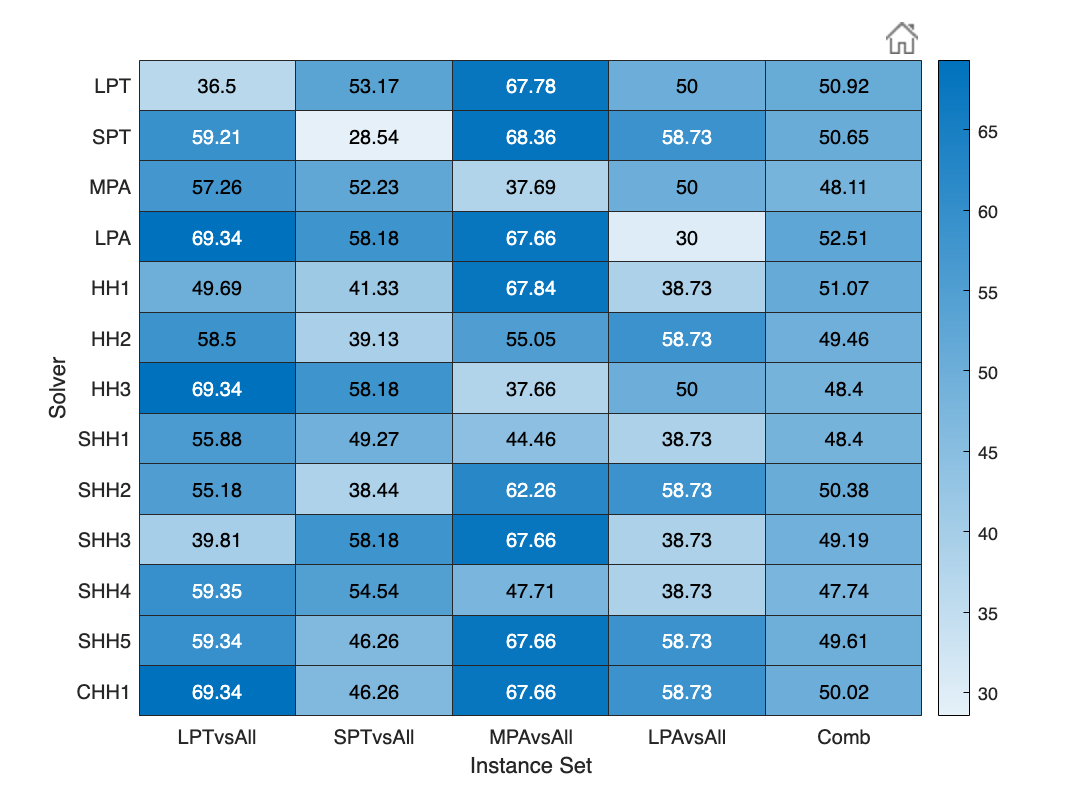

heatmap_FM_7 =   HeatmapChart with properties:

        XData: {5×1 cell}
        YData: {13×1 cell}
    ColorData: [13×5 double]

  Show all properties


heatmap_FM_7.YDisplayLabels={'LPT','SPT','MPA','LPA','HH1','HH2','HH3','SHH1','SHH2','SHH3','SHH4','SHH5','CHH1'};
heatmap_FM_7.XDisplayLabels={'LPTvsAll','SPTvsAll','MPAvsAll','LPAvsAll','Comb'};
heatmap_FM_7.YLabel={'Solver'};
heatmap_FM_7.XLabel={'Instance Set'}

**SAVING VARIABLES **

save('FM_Exp7_results_heatmap',"heatmap_FM_7")
save('FM_Exp7_results_matrix','Results_visualization')
save('FM_Exp7_results_table',"Results_FM_Exp7_4")